# M3 Vision error estimation


clc;clear;close all;

estimates = load('vision_M3_test/M3Performance.txt');
estimates = estimates(1:(240 - 90),:);
poses = load('vision_M3_test/M3realMesurements.txt');
poses = poses(1:30,:);
all_epsilon_t = ones(30, size(estimates,1)/30);
epsilon_t = ones(30, 1);
for i = 1:size(estimates,1)/30
    offset = (i - 1)*30
    for j = 1:30
        pose_estimate = estimates(j + offset, 2:4);
        pose = poses(j, 1:3);
        delta_P = pose_estimate - pose;
        epsilon_t(j) = sqrt(sum(delta_P.^2));
    end
    all_epsilon_t(:,i) = epsilon_t;
end

offset = 0

offset = 30

offset = 60

offset = 90

offset = 120

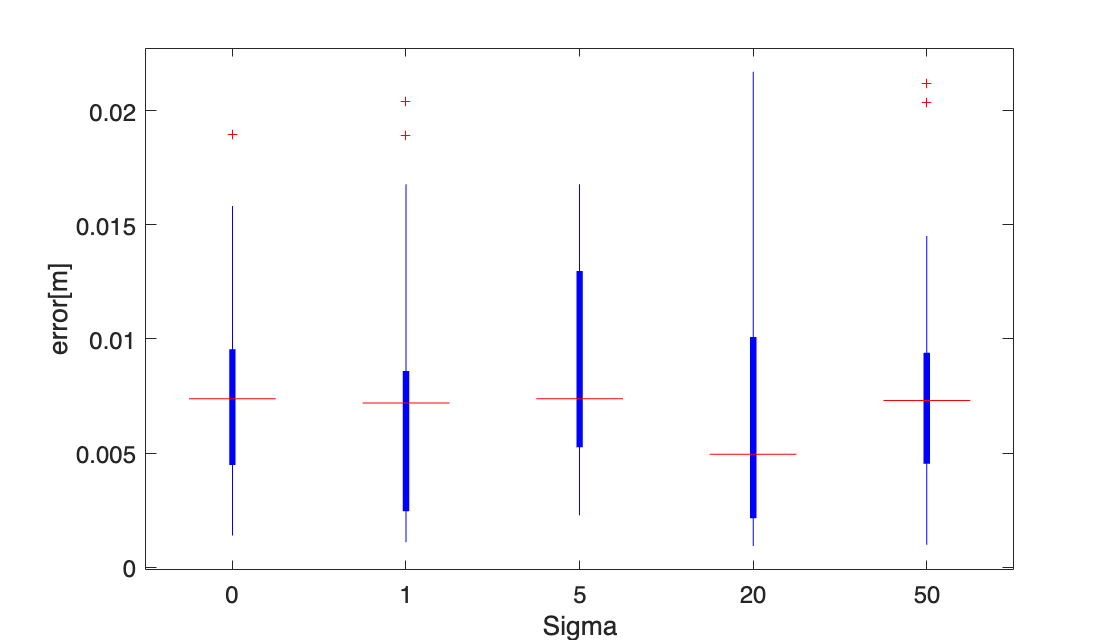


error_levels = [0 1 5 20 50];


%%% outliers rmoutliers
% Remove outliers from all_epsilon_t
all_epsilon_t_no_outliers = rmoutliers(all_epsilon_t);

% Create a figure for the box plot
figure('Name', 'Epsilon_t')

% Plot the box plot of all_epsilon_t_no_outliers with error_levels on the x-axis
boxplot(all_epsilon_t_no_outliers, error_levels,'BoxStyle','filled')

% Add x-axis and y-axis labels and set the font size
xlabel('Sigma','FontSize',20)
ylabel('error[m]','FontSize',20)
set(gca,'FontSize',15)

% Set the position and size of the figure
set(gcf,'position',[0,0,700,400])

%

estimates = load('vision_M3_test/M3Performance.txt');
poses = load('vision_M3_test/M3realMesurements.txt');
poses = poses(1:30,:);
all_epsilon_t = ones(30, size(estimates,1)/30);
epsilon_t = ones(30, 1);
for i = 1:size(estimates,1)/30
    offset = (i - 1)*30
    for j = 1:30
        pose_estimate = estimates(j + offset, 2:4);
        pose = poses(j, 1:3);
        delta_P = pose_estimate - pose;
        epsilon_t(j) = sqrt(sum(delta_P.^2));
    end
    all_epsilon_t(:,i) = epsilon_t;
end

offset = 0

offset = 30

offset = 60

offset = 90

offset = 120

offset = 150

offset = 180

offset = 210

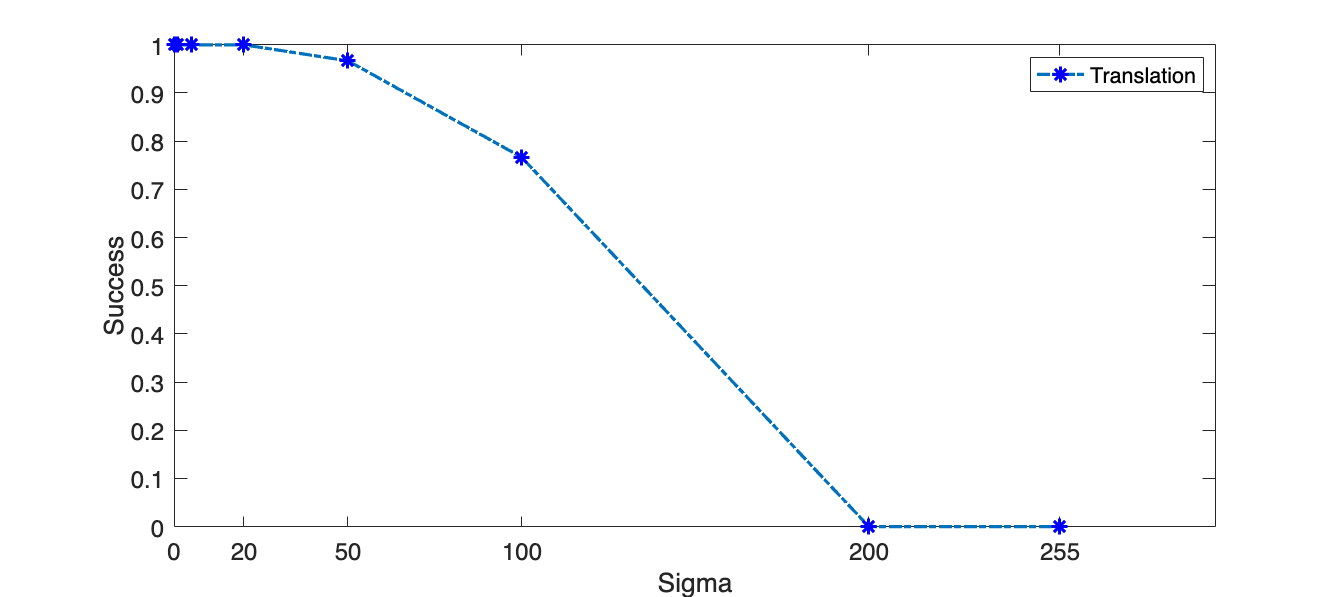


error_levels = [0 1 5 20 50 100 200 255];

figure('Name', 'Performance: Translation')
T_t = 0.05;
T_r = deg2rad(45);
for i = 1:size(estimates,1)/30
    performance_t(i) = size(find(all_epsilon_t(:,i) <= T_t),1)/size(all_epsilon_t,1);
end
plot(error_levels, performance_t,'-.*',...
    'LineWidth',2,...
    'MarkerSize',10,...
    'MarkerEdgeColor','b',...
    'MarkerFaceColor',[0.5,0.5,0.5])

xticks([0 20 50 100 200 255])
legend('Translation')
xlabel('Sigma','FontSize',20)
ylabel('Success','FontSize',20)
set(gca,'FontSize',15)
set(gcf,'position',[0,0,900,400])


%% Time analysis
times = load('vision_M3_test/M3PerformanceTime.txt');
mean_times = mean(times)/10^3 % ms

mean_times = 30.4825

mean_times_std = std(times)/10^3 % ms

mean_times_std = 29.4384


times = load('vision_M3_test/M3PerformaceTimeSTD0.txt');
mean_times = mean(times)/10^3 % ms

mean_times = 4.9881

mean_times_std = std(times)/10^3 % ms

mean_times_std = 0.3033


poses = load('vision_M3_test/M3realMesurements.txt');
poses = poses(1:30,:);
pose_estimates = load('vision_M3_test/M3PerforamanceSTD0.txt');
pose_estimates(:,1) = [];

pos_dif = pose_estimates - poses;
a = sqrt(sum(pos_dif.^2,2));
mean_pos_dif = mean(a)

mean_pos_dif = 0.0068

std_pos_dif = std(a)

std_pos_dif = 0.0032